N=400;          %粒子链总长度
J=100;          %相互作用强度
tmax=5;       %模拟时间
Nt=1000;         %时间采样数
NA=100;         %波包初态中心位置
Ng=200;         %散射粒子位置
phi=pi/2;
delta=30;      %波包半宽
loop=true;
method='ode';
g=2*J;

psi0 = GaussianState(N, NA, phi, delta);
H0 = Hamilton(N, J, loop);
for ii = (N-50):N
    H0(ii,ii) = -1*(abs(ii-N+50))*1i;
end
for ii = 1:50
    H0(ii,ii) = -1*(abs(ii-50))*1i;
end

H = H0;
H(Ng, Ng+1) = g;
H(Ng+1, Ng) = g;
opts = odeset('Reltol', 1e-8, 'AbsTol', 1e-10);
[VEC,D] = eig(H);
tic
[t,psi] = psicalc(H, psi0, tmax, 'ode', opts);
toc

历时 1.815076 秒。


gs = (0:0.1:5)*J;
tic
parfor ii = 1:length(gs)
    H=H0;                  %parfor不能修改共用变量，所以要每个线程复制一份分别修改
    H(Ng, Ng+1) = gs(ii);
    H(Ng+1, Ng) = gs(ii);
    [VEC, D] = eig(H);
    [t, psi] = psicalc(H, psi0, tmax, 'eig', 10, VEC, D);
    T(ii) = max(vecnorm(psi(:, Ng:N), 2, 2))^2;
end
toc

历时 7.027620 秒。


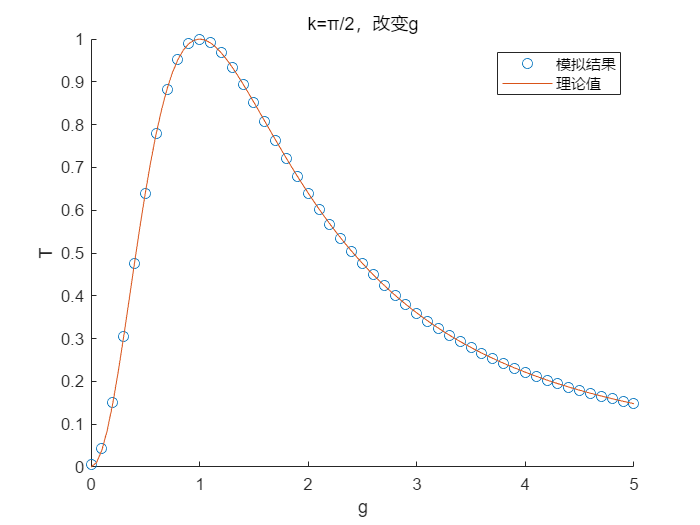

scatter(gs / J, T)
hold on
x=0:0.05:5;
y=(4*x.^2)./((x.^2+1).^2);
plot(x, y, '-');
hold off
legend('模拟结果', '理论值')
xlabel('g')
ylabel('T')
title('k=\pi/2，改变g')

ks = (0:0.02:1) * pi;
H = H0;
H(Ng, Ng+1) = g;
H(Ng+1, Ng) = g;
[VEC, D] = eig(H);
tic
T = zeros(1, length(ks));
parfor ii = 1:length(ks)
    psi0 = GaussianState(N, NA, ks(ii), delta);
    [~, psi] = psicalc(H, psi0, tmax, 'eig', 20, VEC, D);
    T(ii) = max(vecnorm(psi(:, Ng:N), 2, 2))^2;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


toc

历时 23.915914 秒。


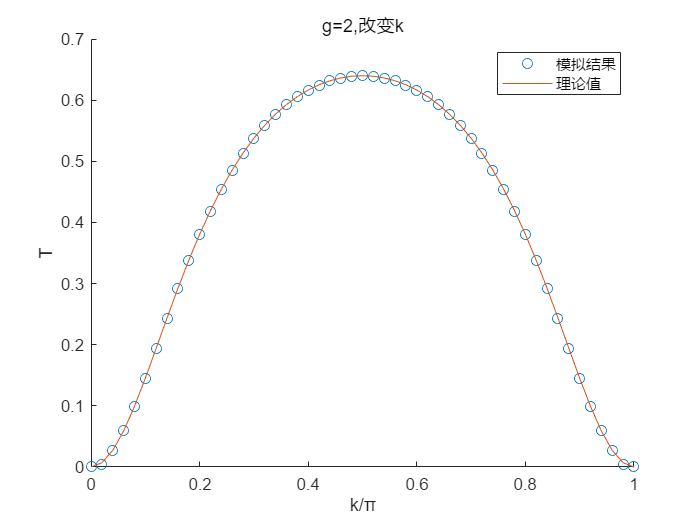

scatter(ks / pi, T)
hold on
x = 0:0.02:1;
g1 = g / J;
y = (4 * g1^2 * sin( x * pi ) .^ 2)./((g1^2 + 1)^2 * (sin(x * pi).^2) + (g1^2 - 1)^2 * (cos(x * pi).^2));
plot(x, y)
hold off
legend('模拟结果', '理论值')
xlabel('k/\pi')
ylabel('T')
title('g=2,改变k')

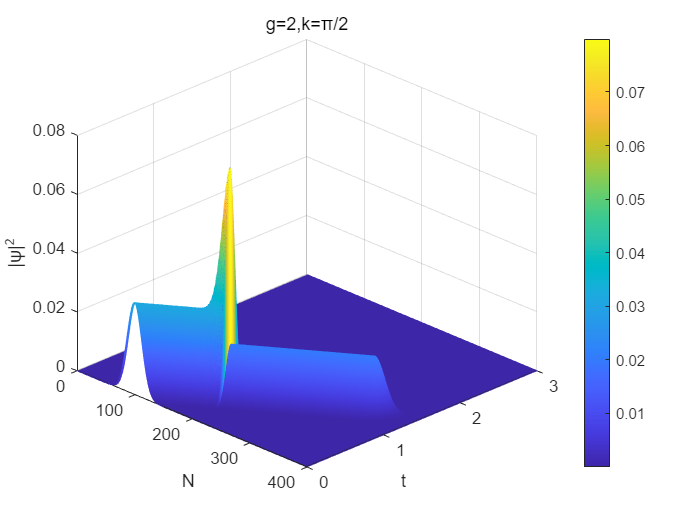

%ode方法数据太多，画图容易卡，抽样一部分用来画图即可
if strcmp(method,'ode')
    dt = floor( length(t) / Nt );
    tplot = t(1:dt:end);
    psiplot = psi(1:dt:end,:);
else
    tplot = t;
    psiplot = psi;
end

plotpsi(psiplot,tplot,N)
title('g=2,k=\pi/2')